clc; clear all;

warning('off','all')
% создаем карту
% map = makemap(100)
% save map_try.mat

%% планирование траектории методом вероятностной дорожной карты
% load map_try.mat
% 
% map = binaryOccupancyMap(map);
% prmSimple = mobileRobotPRM(map,1e3);
% startLocation = [40 2];
% endLocation = [90 90];
% path = findpath(prmSimple,startLocation,endLocation);
% figure
% show(prmSimple)
% 
% options = optimizePathOptions;
% options.ObstacleSafetyMargin = 1;
% 
% optPath = optimizePath(path,map,options);
% hold on
% grid minor
% plot(path(:,1),path(:,2),'Color','r','LineWidth',2)
% plot(optPath(:,1),optPath(:,2),'Color','g','LineWidth',2)
% legend("RPM_{lines}","RPM_{dots}","","Planned Path","Optimez Path",'Location','eastoutside')
% hold off


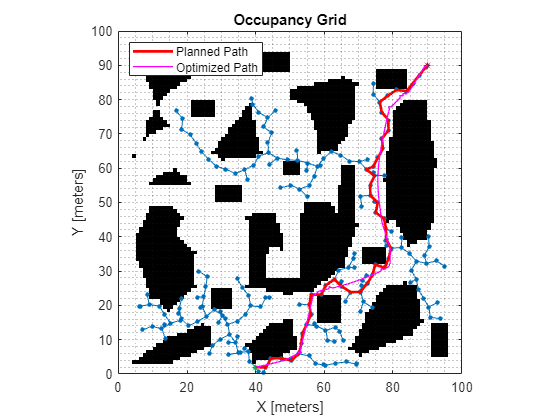

%% планирование трпектории методом быстроисследующего случайного дерева
load map_try.mat

% создает пространство состояний для планирования пути робота
ss = stateSpaceSE2;
% создает валидатор (проверяющий) пути на основе заданной карты препятствий
sv = validatorOccupancyMap(ss);
% загружаем карту препятствий
map = occupancyMap(map);
sv.Map = map;
% задаем минимальное расстояние между двумя состояниями, которые должны быть проверены на достижимость
sv.ValidationDistance = 0.1;
% задаем границы пространства состояний
ss.StateBounds = [map.XWorldLimits;map.YWorldLimits; [-pi pi]];
% создаем планировщик на основе пространства состояний и валидатора пути
planner = plannerRRT(ss,sv);
% задаем максимальную дистанцию между двумя состояниями, которые могут быть соединены в дереве RRT
planner.MaxConnectionDistance = 3;

% задаем начальную точку [x, y, yaw] 
% угол рыскания на траектории мы держим постоянным yaw = 0
start = [40,2,0];
% задаем конечную точку [x, y, yaw]
goal = [90,90,0];
% задаем высоту
% высоту на тректории мы держим постоянной
z = 5;
% задаем генератор случайных чисел
rng(100,'twister');
% выполняем планирование пути робота на основе заданного планировщика, начального и конечного состояний
[pthObj,solnInfo] = plan(planner,start,goal);

figure(1)
show(map)
hold on
plot(solnInfo.TreeData(:,1),solnInfo.TreeData(:,2),'.-','MarkerSize',10);
p1 = plot(pthObj.States(:,1),pthObj.States(:,2),'r-','LineWidth',2);

plot(start(1),start(2),'*g')
plot(goal(1),goal(2),'*r')

% оптимизируем траекторию
options = optimizePathOptions;
options.ObstacleSafetyMargin = 1;
optPath = optimizePath(pthObj.States,map,options);
hold on
grid minor
p2 = plot(optPath(:,1),optPath(:,2),"m-",LineWidth=1);
legend([p1,p2],"Planned Path","Optimized Path",Location="northwest")
hold off

% выводим параметры траектории для simulink модели
x_des = optPath(:,1);
y_des = optPath(:,2);

## Запуск симуляций

simout_ = sim('quadrotor_project_2021a');

Found algebraic loop containing: 
quadrotor_project_2021a/U2
quadrotor_project_2021a/Control Mixer/Sum7 (algebraic variable)
quadrotor_project_2021a/Control Mixer/Sum12
quadrotor_project_2021a/U3
quadrotor_project_2021a/Control Mixer/Sum5 (algebraic variable)
quadrotor_project_2021a/Control Mixer/Sum11
quadrotor_projec

simout_pd = sim('quadrotor_default_2021a');

## **Строим графики**

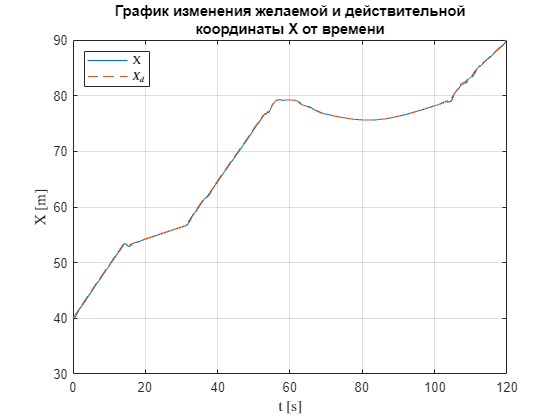

figure(2)
plot(simout_.state.X.Time, simout_.state.X.Data)
hold on
plot(simout_.state_des.x__y_.Time, simout_.state_des.x__y_.Data(:,1), ...
         "LineStyle","--")
grid on
label2 = '${X_d}$';
label1 = 'X';
legend(label1,label2,'Interpreter',"latex",Location="northwest")
xlabel('t [s]','Interpreter',"latex")
ylabel('X [m]','Interpreter',"latex")
title({'График изменения желаемой и действительной', ...
    'координаты Х от времени'})

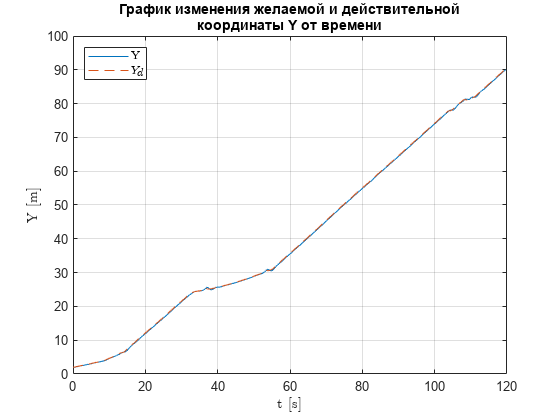


figure(3)
plot(simout_.state.Y.Time, simout_.state.Y.Data)
hold on
plot(simout_.state_des.x__y_.Time, simout_.state_des.x__y_.Data(:,2), ...
         "LineStyle","--")
grid on
legend('Y','${Y_d}$','Interpreter',"latex",Location="northwest")
xlabel('t [s]','Interpreter',"latex")
ylabel('Y [m]','Interpreter',"latex")
title({'График изменения желаемой и действительной', ...
    'координаты Y от времени'})

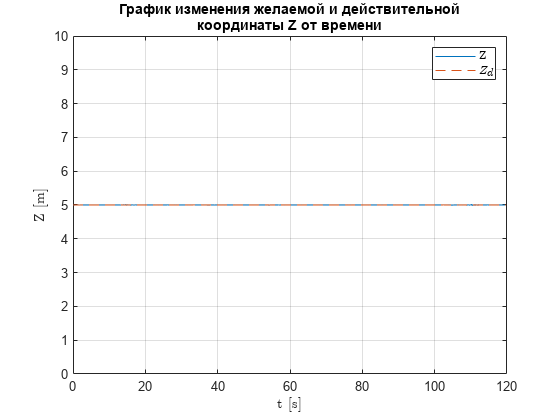



figure(4)
plot(simout_.state.Z.Time, (simout_.state.Z.Data) * (-1))
hold on
plot(simout_.state.Z.Time, ones(1,length(simout_.state.Z.Time)) * ...
    simout_.state_des.z_des.Data,"LineStyle","--")
grid on
label2 = '${Z_d}$';
label1 = 'Z';
legend(label1,label2,'Interpreter',"latex")
xlabel('t [s]','Interpreter',"latex")
ylabel('Z [m]','Interpreter',"latex")
ylim([0,10])
title({'График изменения желаемой и действительной', ...
    'координаты Z от времени'})

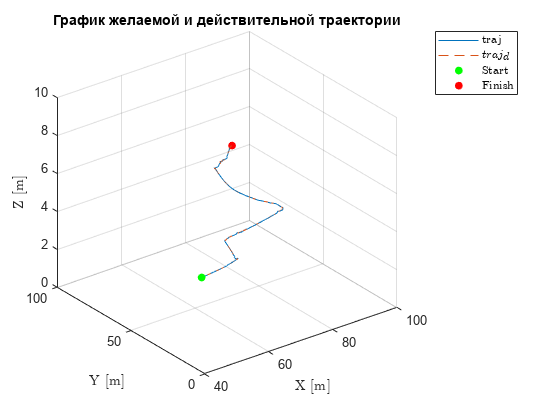


figure(5)
plot3(simout_.state.X.Data, simout_.state.Y.Data, (simout_.state.Z.Data) * (-1))
hold on
plot3(simout_.state_des.x__y_.Data(:,1), simout_.state_des.x__y_.Data(:,2), ...
    ones(1,length(simout_.state.Z.Time)) * ...
    simout_.state_des.z_des.Data,"LineStyle","--")
hold on
plot3(start(1),start(2),z,'g.','MarkerSize', 20)
hold on
plot3(goal(1),goal(2),z,'r.','MarkerSize', 20)
grid on
label1 = 'traj';
label2 = '${traj_d}$';
label3 = 'Start';
label4 = 'Finish';
legend(label1,label2,label3,label4,'Interpreter',"latex")
xlabel('X [m]','Interpreter',"latex")
ylabel('Y [m]','Interpreter',"latex")
zlabel('Z [m]','Interpreter',"latex")
zlim([0,10])
title('График желаемой и действительной траектории')

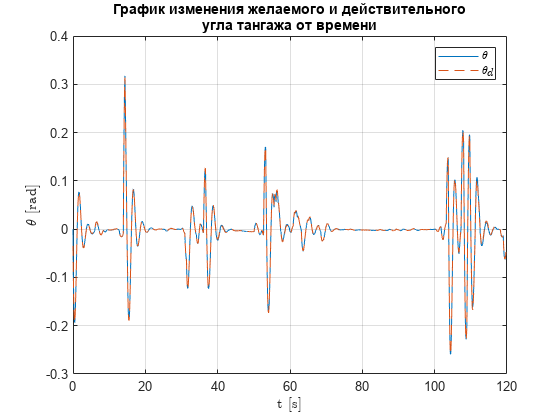


figure(6)
plot(simout_.state.pitch.Time, simout_.state.pitch.Data)
hold on
plot(simout_.state_des.roll__pitch_.Time, simout_.state_des.roll__pitch_.Data(:,2), ...
         "LineStyle","--")
grid on
label2 = '${\theta_d}$';
label1 = '${\theta}$';
legend(label1,label2,'Interpreter',"latex")
xlabel('t [s]','Interpreter',"latex")
ylabel('${\theta}$ [rad]','Interpreter',"latex")
title({'График изменения желаемого и действительного', ...
    'угла тангажа от времени'})

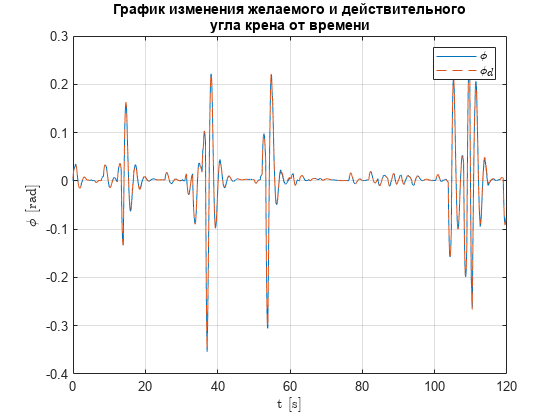



figure(7)
plot(simout_.state.roll.Time, simout_.state.roll.Data)
hold on
plot(simout_.state_des.roll__pitch_.Time, simout_.state_des.roll__pitch_.Data(:,1), ...
         "LineStyle","--")
grid on
label2 = '${\phi_d}$';
label1 = '${\phi}$';
legend(label1,label2,'Interpreter',"latex")
xlabel('t [s]','Interpreter',"latex")
ylabel('${\phi}$ [rad]','Interpreter',"latex")
title({'График изменения желаемого и действительного', ...
    'угла крена от времени'})

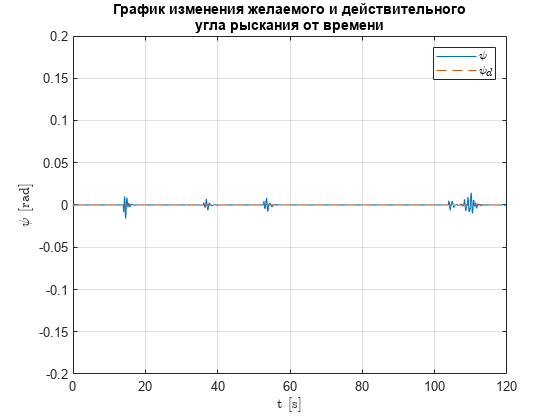


figure(8)
plot(simout_.state.yaw.Time, simout_.state.yaw.Data)
hold on
plot(simout_.state.yaw.Time, zeros(1,length(simout_.state.yaw.Time)), ...
         "LineStyle","--")
grid on
label2 = '${\psi_d}$';
label1 = '${\psi}$';
legend(label1,label2,'Interpreter',"latex")
xlabel('t [s]','Interpreter',"latex")
ylabel('${\psi}$ [rad]','Interpreter',"latex")
ylim([-0.2,0.2])
title({'График изменения желаемого и действительного', ...
    'угла рыскания от времени'})

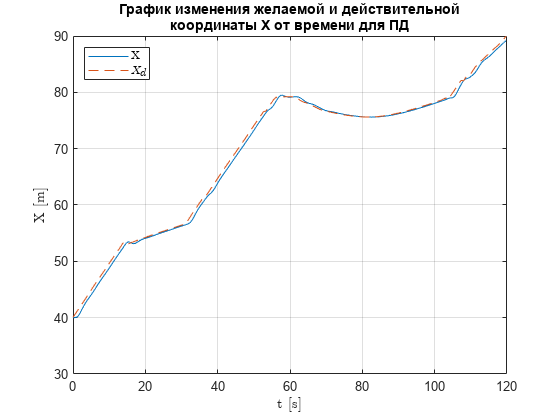


% графики для ПД

figure(9)
plot(simout_pd.state.X.Time, simout_pd.state.X.Data)
hold on
plot(simout_pd.state_des.x__y_.Time, simout_pd.state_des.x__y_.Data(:,1), ...
         "LineStyle","--")
grid on
label1 = 'X';
label2 = '${X_d}$';
legend(label1,label2,'Interpreter',"latex",Location="northwest")
xlabel('t [s]','Interpreter',"latex")
ylabel('X [m]','Interpreter',"latex")
title({'График изменения желаемой и действительной', ...
    'координаты Х от времени для ПД'})

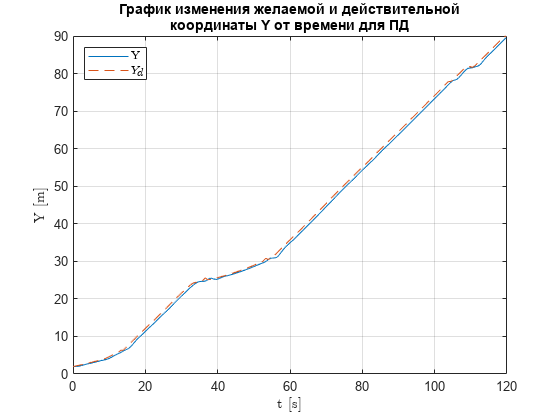


figure(10)
plot(simout_pd.state.Y.Time, simout_pd.state.Y.Data)
hold on
plot(simout_pd.state_des.x__y_.Time, simout_pd.state_des.x__y_.Data(:,2), ...
         "LineStyle","--")
grid on
label1 = 'Y';
label2 = '${Y_d}$';
legend(label1,label2,'Interpreter',"latex",Location="northwest")
xlabel('t [s]','Interpreter',"latex")
ylabel('Y [m]','Interpreter',"latex")
title({'График изменения желаемой и действительной', ...
    'координаты Y от времени для ПД'})

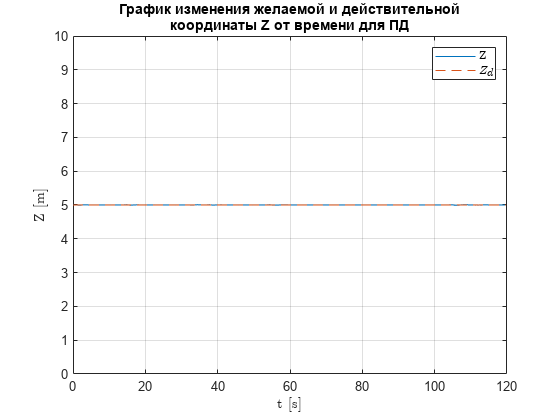



figure(11)
plot(simout_pd.state.Z.Time, (simout_pd.state.Z.Data) * (-1))
hold on
plot(simout_pd.state_des.z_des.Time, (simout_pd.state_des.z_des.Data) * (-1),"LineStyle","--")
grid on
label2 = '${Z_d}$';
label1 = 'Z';
legend(label1,label2,'Interpreter',"latex")
xlabel('t [s]','Interpreter',"latex")
ylabel('Z [m]','Interpreter',"latex")
ylim([0,10])
title({'График изменения желаемой и действительной', ...
    'координаты Z от времени для ПД'})

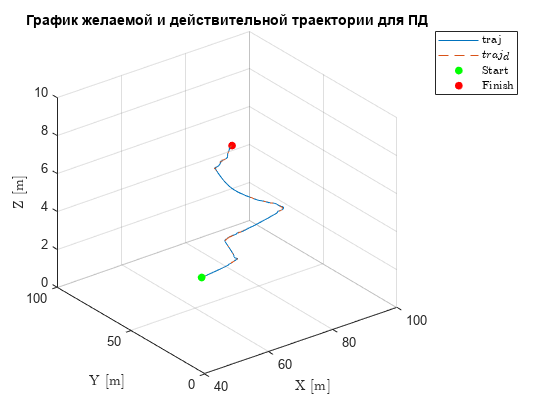


figure(12)
plot3(simout_pd.state.X.Data, simout_pd.state.Y.Data, (simout_pd.state.Z.Data) * (-1))
hold on
plot3(simout_pd.state_des.x__y_.Data(:,1), simout_pd.state_des.x__y_.Data(:,2), ...
    (simout_pd.state_des.z_des.Data) * (-1),"LineStyle","--")
hold on
plot3(start(1),start(2),z,'g.','MarkerSize', 20)
hold on
plot3(goal(1),goal(2),z,'r.','MarkerSize', 20)
grid on
label1 = 'traj';
label2 = '${traj_d}$';
label3 = 'Start';
label4 = 'Finish';
legend(label1,label2,label3,label4,'Interpreter',"latex")
xlabel('X [m]','Interpreter',"latex")
ylabel('Y [m]','Interpreter',"latex")
zlabel('Z [m]','Interpreter',"latex")
zlim([0,10])
title('График желаемой и действительной траектории для ПД')

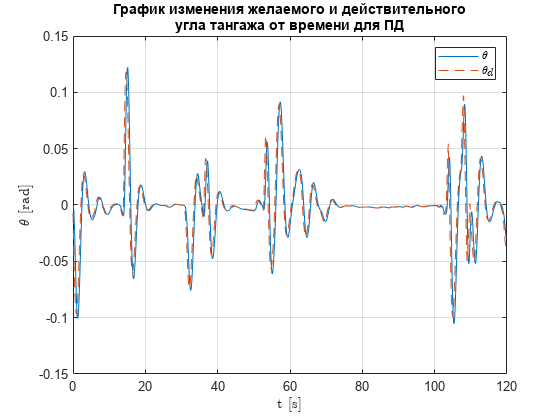



figure(13)
plot(simout_pd.state.pitch.Time, simout_pd.state.pitch.Data)
hold on
plot(simout_pd.state_des.roll__pitch_.Time, simout_pd.state_des.roll__pitch_.Data(:,2), ...
         "LineStyle","--")
grid on
label2 = '${\theta_d}$';
label1 = '${\theta}$';
legend(label1,label2,'Interpreter',"latex")
xlabel('t [s]','Interpreter',"latex")
ylabel('${\theta}$ [rad]','Interpreter',"latex")
title({'График изменения желаемого и действительного', ...
    'угла тангажа от времени для ПД'})

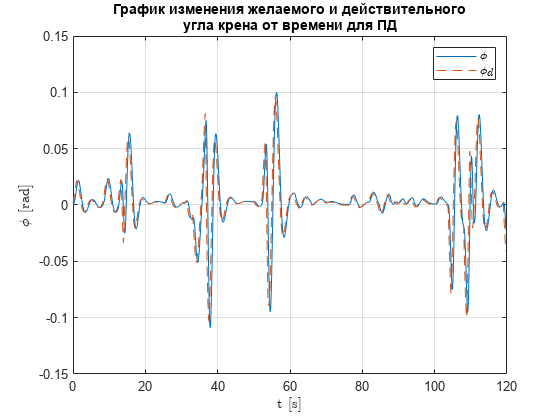



figure(14)
plot(simout_pd.state.roll.Time, simout_pd.state.roll.Data)
hold on
plot(simout_pd.state_des.roll__pitch_.Time, simout_pd.state_des.roll__pitch_.Data(:,1), ...
         "LineStyle","--")
grid on
label2 = '${\phi_d}$';
label1 = '${\phi}$';
legend(label1,label2,'Interpreter',"latex")
xlabel('t [s]','Interpreter',"latex")
ylabel('${\phi}$ [rad]','Interpreter',"latex")
title({'График изменения желаемого и действительного', ...
    'угла крена от времени для ПД'})

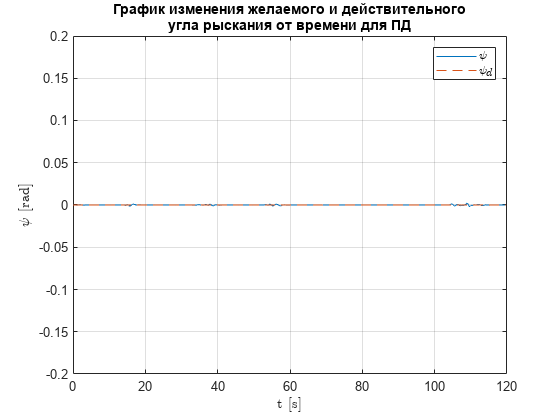


figure(15)
plot(simout_pd.state.yaw.Time, simout_pd.state.yaw.Data)
hold on
plot(simout_pd.state.yaw.Time, zeros(1,length(simout_pd.state.yaw.Time)), ...
         "LineStyle","--")
grid on
label2 = '${\psi_d}$';
label1 = '${\psi}$';
legend(label1,label2,'Interpreter',"latex")
xlabel('t [s]','Interpreter',"latex")
ylabel('${\psi}$ [rad]','Interpreter',"latex")
ylim([-0.2,0.2])
title({'График изменения желаемого и действительного', ...
    'угла рыскания от времени для ПД'})

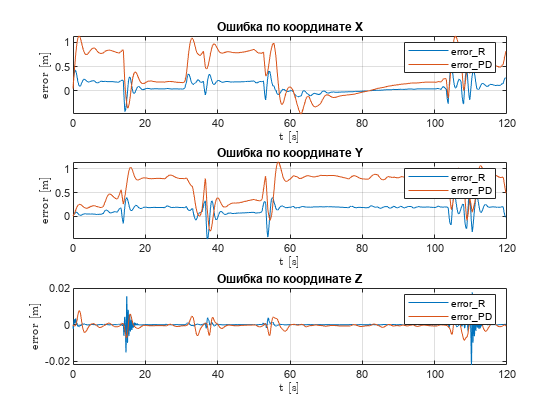

%%%%%%%%%%%%%%%%%%

% считаем ошибку по координатам для навороченного 
error_x_R = (simout_.state_des.x__y_.Data(:,1) - simout_.state.X.Data);
error_y_R = (simout_.state_des.x__y_.Data(:,2) - simout_.state.Y.Data);
error_z_R = (ones(length(simout_.state.Z.Time),1) * ...
    simout_.state_des.z_des.Data - (simout_.state.Z.Data) * (-1));

% считаем ошибку по координатам для ПД 
error_x_PD = (simout_pd.state_des.x__y_.Data(:,1) - simout_pd.state.X.Data);
error_y_PD = (simout_pd.state_des.x__y_.Data(:,2) - simout_pd.state.Y.Data);
error_z_PD = ((simout_pd.state_des.z_des.Data) * (-1) - (simout_pd.state.Z.Data) * (-1));

% считаем ошибку по углам для навороченного 
error_pitch_R = abs(simout_.state_des.roll__pitch_.Data(:,2) - simout_.state.pitch.Data);
error_yaw_R = abs(zeros(length(simout_.state.yaw.Time), 1) - simout_.state.yaw.Data);
error_roll_R = abs(simout_.state_des.roll__pitch_.Data(:,1) - simout_.state.roll.Data);

% считаем ошибку по углам для ПД 
error_pitch_PD = (simout_pd.state_des.roll__pitch_.Data(:,2) - simout_pd.state.pitch.Data);
error_yaw_PD = (zeros(length(simout_pd.state.yaw.Time),1) - simout_pd.state.yaw.Data);
error_roll_PD = (simout_pd.state_des.roll__pitch_.Data(:,1) - simout_pd.state.roll.Data);

error_Rc = [error_x_R error_y_R error_z_R];
error_Ra = [error_pitch_R error_yaw_R error_roll_R];
error_PDc = [error_x_PD error_y_PD error_z_PD];
error_PDa = [error_pitch_PD error_yaw_PD error_roll_PD];
ttlec = {'Ошибка по координате X', 'Ошибка по координате Y', 'Ошибка по координате Z'};
ttlea = {'Ошибка по углу тангажа', 'Ошибка по углу рыскания', 'Ошибка по углу крена'};



figure(16)
for i = 1 : size(error_Rc,2)
    subplot(3,1,i)
    plot(simout_.state.X.Time, error_Rc(:,i))
    hold on
    plot(simout_pd.state.X.Time, error_PDc(:,i))
    grid on
    label1 = 'error_R';
    label2 = 'error_PD';
    legend(label1,label2,'Interpreter',"latex")
    xlabel('t [s]','Interpreter',"latex")
    ylabel('error [m]','Interpreter',"latex")
    title(ttlec{i})
end

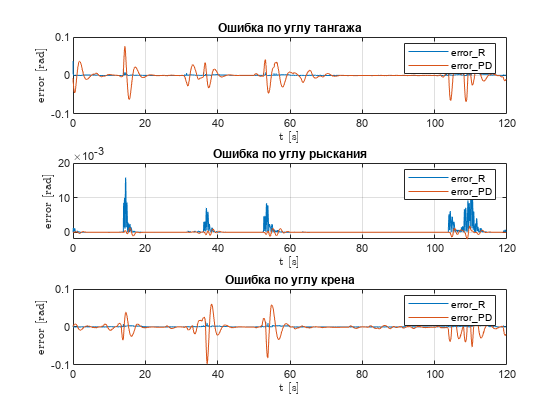


figure(17)
for i = 1 : size(error_Ra,2)
    subplot(3,1,i)
    plot(simout_.state.X.Time, error_Ra(:,i))
    hold on
    plot(simout_pd.state.X.Time, error_PDa(:,i))
    grid on
    label1 = 'error_R';
    label2 = 'error_PD';
    legend(label1,label2,'Interpreter',"latex")
    xlabel('t [s]','Interpreter',"latex")
    ylabel('error [rad]','Interpreter',"latex")
    title(ttlea{i})
end

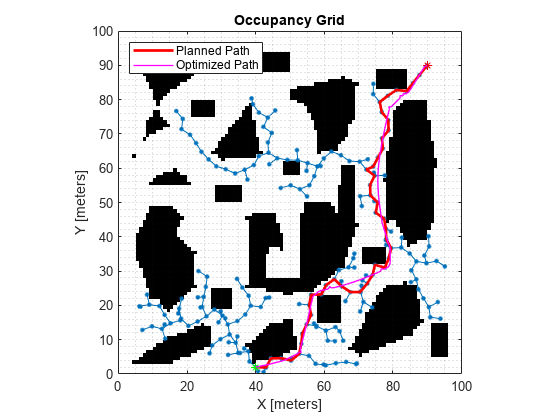

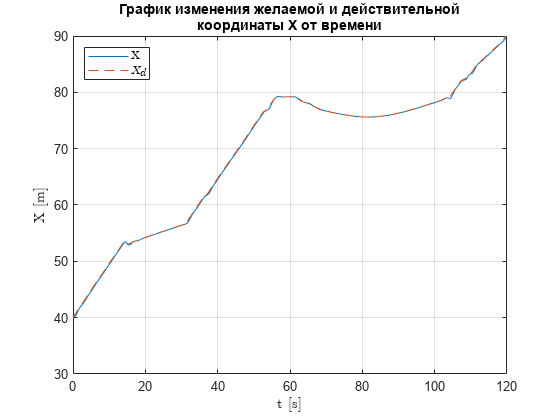

mkdir images
str = [pwd,"images"];
pathdir =  join(str,"\");
cd(pathdir)
for i = 1 : 17
    exportgraphics(figure(i),[num2str(i),'.png'],'Resolution',1200);
end